# Polinomi di Chebyshev

Polinomi di grado crescente $T_0 \left(x\right),T_1 \left(x\right),\ldotp \ldotp \ldotp T_n \left(x\right)$ definiti nell'intervallo [-1,1] nel seguente modo:


$$T_n \left(x\right)=\mathrm{cos}\left(n*\mathrm{arcos}\left(x\right)\right)$$


Pertanto vale la relazione di ricorrenza:


$$T_{n+1} \left(x\right)=2*x*T_n \left(x\right)-T_{n-1} \left(x\right)$$


In generale per disegnare un polinomio di Chebyshev si disegna una semicirconferenza goniometrica (di centro l’origine degli assi e raggio 1) e la si divide in 2*n *archi di uguale lunghezza. Le proiezioni dei 2*n *+ 1 estremi sull’asse *x *sono, da destra a sinistra, punto di massimo, zero, punto di minimo, zero, e cosi via di $T_n \left(x\right)$.

Il calcolo di n nodi di Chebyshev si ottiene con la formula :


$$z_k =\mathrm{cos}\left(\frac{\left(2k+1\right)\pi }{2n}\right)\;\;\;\;\;\;\;k=0,1,\ldotp \ldotp \ldotp ,n-1$$


n=6;

punti = cos( (2*[0:n-1]'+1)*pi/(2*n) ); %%ATTENZIONE
disp(punti);

    0.9659
    0.7071
    0.2588
   -0.2588
   -0.7071
   -0.9659




space=linspace(-1,1,1000);

cheby6=@(x) (2*x.*(16*x.^5-20*x.^3+ 5*x)-(8*x.^4-8*x.^2+1));

subplot(2,1,1);
plot(space,cheby6(space),'-');




Per mappare i punti su un intervallo a piacere


$$x=\frac{b-a}{2}*z+\frac{a+b}{2}$$


a=0;
b=10;
%Rimappatura
x=(b-a)/2.*punti +(a+b)/2;
disp(x);

    9.8296
    8.5355
    6.2941
    3.7059
    1.4645
    0.1704



space_ten=linspace(0,10,6);

Per determinare il numero minimo di nodi per avere una precisone $\tau$ vogliamo che  ${||\omega \left(x\right)||}_{\infty } \;$sia il minimo possibile. Per ottenere cio abbiamo che ${\left|\right|\omega \left(x\right)\left|\right|}_{\infty } =2{\left(\frac{b-a}{4}\right)}^{n+1}$. Pe ottenere l'errore minimo sostituiamo questo valore di omega nella formula dell'errore di interpolazione.

$|R\left(x\right)|=\frac{|f^{n+1} \left(x\right)|\;|\omega \left(x\right)|}{\left(n+1\right)!}$ --> Per Numero di nodi Di Chebyshev --> $\left|R\left(x\right)\right|=\frac{\left|f^{n+1} \left(x\right)\right|}{\left(n+1\right)!}*2{\left(\frac{b-a}{4}\right)}^{n+1}$

Esercizio Di Dimostrazione

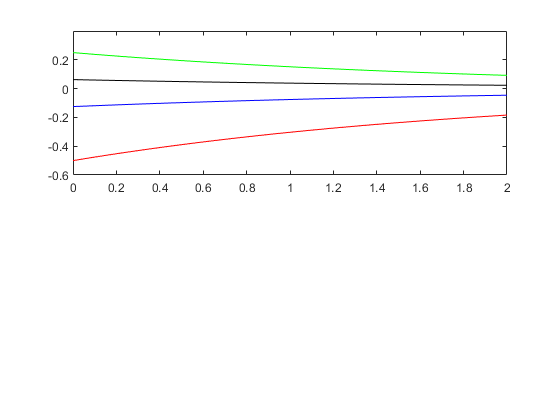

functi=@(x) exp(-x/2);
tau=1e-3;
a=0;b=2;
deresp=-0.5;

derprima=@(x) deresp*functi(x);
desec=@(x) deresp*derprima(x);
deter=@(x) deresp*desec(x);
dequar=@(x) deresp*deter(x);
puntuderi=linspace(a,b,100);

hold off

plot(puntuderi,derprima(puntuderi),'r')
hold on
plot(puntuderi,desec(puntuderi),'g')
hold on
plot(puntuderi,deter(puntuderi),'b')
hold on
plot(puntuderi,dequar(puntuderi),'k')

Posso maggiorare la derivata $\left|f^{n+1} \left(x\right)\right|\le 1\;\mathrm{in}\;\left\lbrack 0,2\right\rbrack$ 

Perciò la maggiorazione dell'errore di interpolazione relativa ai Nodi di Chebyshev è:


$$\left|R\left(x\right)\right|=\frac{\left|f^{n+1} \left(x\right)\right|}{\left(n+1\right)!}*2{\left(\frac{b-a}{4}\right)}^{n+1} \le \frac{1}{\left(n+1\right)!}$$

$$2{\left(\frac{b-a}{4}\right)}^{n+1} =\frac{2}{\left(n+1\right)!}{\left(\frac{2}{4}\right)}^{n+1} \le \tau =10^{-3}$$


rx=@(x) (2/factorial(x+1)*(0.5^(x+1)))

rx = function_handle with value:
    @(x)(2/factorial(x+1)*(0.5^(x+1)))



disp(findminnode(rx,tau))

RUNIING FUNCTION
     1

     2

     3

     4

END
     4



function n = findminnode(fun,tau)
disp("RUNIING FUNCTION");
stop=0;
counter=1;
while(~stop)
if(fun(counter)<tau)
    
    stop=1;
    n=counter;
end
disp(counter);
counter= counter+1;
    
end
disp("END");
end